## double & threshold

cameraman = imread("cameraman.tif")

cameraman = 256×256 uint8 矩阵
   156   159   158   155   158   156   159   158   157   158   158   159   160   160   160   158   163   161   162   160   164   160   165   163   161   163   161   164   165   162   161   165   165   164   166   165   164   166   167   165   165   164   170   166   167   167   170   168   169   166
   160   154   157   158   157   159   158   158   158   160   155   156   159   158   160   157   165   159   161   158   162   162   161   163   159   162   164   163   164   165   169   164   163   165   161   163   165   168   167   165   164   163   169   169   169   170   170   169   170   170
   156   159   158   155   158   156   159   158   157   158   158   159   160   160   160   158   163   161   162   160   164   160   165   163   161   163   161   164   165   162   161   165   165   164   166   165   164   166   167   165   165   164   170   166   167   167   170   168   169   166
   160   154   157   158   157   159   158   158   158   160   155  

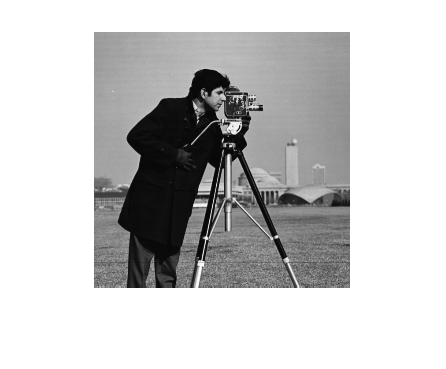

imshow(cameraman)


cameraman_double1 = double(cameraman)    

cameraman_double1 =    156   159   158   155   158   156   159   158   157   158   158   159   160   160   160   158   163   161   162   160   164   160   165   163   161   163   161   164   165   162   161   165   165   164   166   165   164   166   167   165   165   164   170   166   167   167   170   168   169   166
   160   154   157   158   157   159   158   158   158   160   155   156   159   158   160   157   165   159   161   158   162   162   161   163   159   162   164   163   164   165   169   164   163   165   161   163   165   168   167   165   164   163   169   169   169   170   170   169   170   170
   156   159   158   155   158   156   159   158   157   158   158   159   160   160   160   158   163   161   162   160   164   160   165   163   161   163   161   164   165   162   161   165   165   164   166   165   164   166   167   165   165   164   170   166   167   167   170   168   169   166
   160   154   157   158   157   159   158   158   158   160   155   156   15

imshow(cameraman_double1)

imshow(cameraman_double1/255)


% or
cameraman_double2 = im2double(cameraman)

cameraman_double2 =     0.6118    0.6235    0.6196    0.6078    0.6196    0.6118    0.6235    0.6196    0.6157    0.6196    0.6196    0.6235    0.6275    0.6275    0.6275    0.6196    0.6392    0.6314    0.6353    0.6275    0.6431    0.6275    0.6471    0.6392    0.6314    0.6392    0.6314    0.6431    0.6471    0.6353    0.6314    0.6471    0.6471    0.6431    0.6510    0.6471    0.6431    0.6510    0.6549    0.6471    0.6471    0.6431    0.6667    0.6510    0.6549    0.6549    0.6667    0.6588    0.6627    0.6510
    0.6275    0.6039    0.6157    0.6196    0.6157    0.6235    0.6196    0.6196    0.6196    0.6275    0.6078    0.6118    0.6235    0.6196    0.6275    0.6157    0.6471    0.6235    0.6314    0.6196    0.6353    0.6353    0.6314    0.6392    0.6235    0.6353    0.6431    0.6392    0.6431    0.6471    0.6627    0.6431    0.6392    0.6471    0.6314    0.6392    0.6471    0.6588    0.6549    0.6471    0.6431    0.6392    0.6627    0.6627    0.6627    0.6667    0.6667    0.662

imshow(cameraman_double2)

threshold1 = cameraman > 120

threshold1 = 256×256 logical 数组
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1

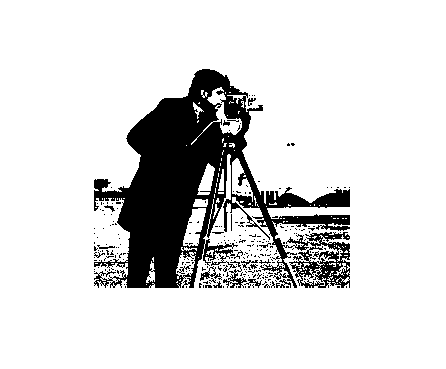

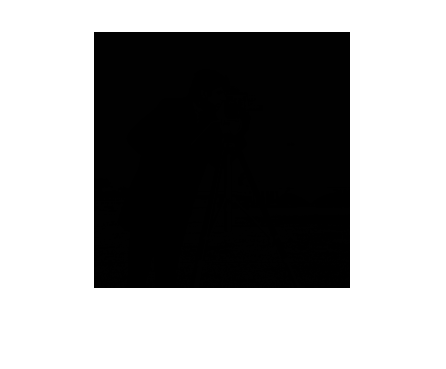

imshow(threshold1)

## bit plane

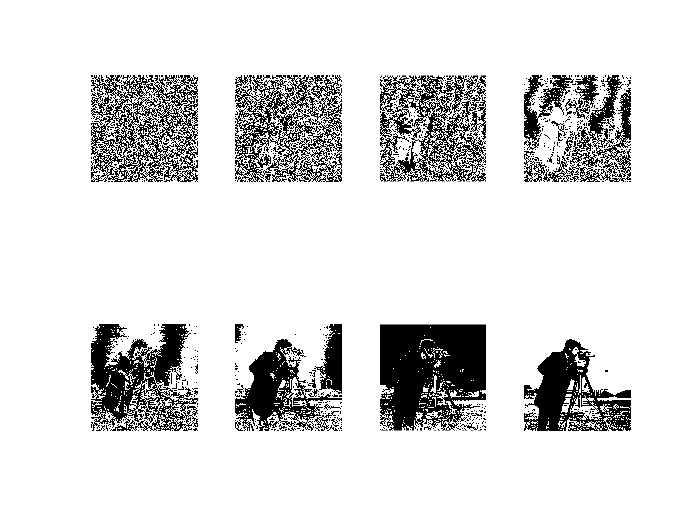

figure()
c0 = mod(cameraman_double1, 2);
subplot(2, 4, 1); imshow(c0)

c1 = mod(floor(cameraman_double1/2), 2);
subplot(2, 4, 2); imshow(c1)

c2 = mod(floor(cameraman_double1/4), 2);
subplot(2, 4, 3); imshow(c2)

c3 = mod(floor(cameraman_double1/8), 2);
subplot(2, 4, 4); imshow(c3)

c4 = mod(floor(cameraman_double1/16), 2);
subplot(2, 4, 5); imshow(c4)

c5 = mod(floor(cameraman_double1/32), 2);
subplot(2, 4, 6); imshow(c5)

c6 = mod(floor(cameraman_double1/64), 2);
subplot(2, 4, 7); imshow(c6)

c7 = mod(floor(cameraman_double1/128), 2);
subplot(2, 4, 8); imshow(c7)

cc = 2*(2*(2*(2*(2*(2*(2*c7 + c6) + c5) + c4) + c3) + c2) + c1) + c0;
figure, imshow(cc/255)

figure, imshow(uint8(cc))

close all